# Example 3.20: Geometry of 2D Gaussian Ellipsoid

Note: this script reproduces Example 3.20 (Section 3.8.5) of **Statistics for Chemical Engineers**: the 95% confidence ellipse of a 2D Gaussian. Victor Z UW-Madison, 2020 illustrate geometry of Gaussian variables

clc;  clear all; close all hidden; format short 

addpath('./Support')

## Model

specify mean and covariance

mu = [0 0];
Sigma = [1 -0.5; 
        -0.5 1]; % anti-correlated

## 95% confidence ellipse

compute the 95% confidence interval ellipse

alpha = 0.95; % confidence 
n = 2; % dimension of variable
A = inv(Sigma); % inverse covariance
b = chi2inv(alpha, n); % confidence level on 2d from chi2 distribution
[xe, ye, major, minor, bbox] = ellipse(A, b, 100, mu); % ellipse

% 95% marginal intervals
b2 = chi2inv(alpha, 1); % confidence level on 1d from chi2 distribution
xd2 = sqrt(b2.*diag(Sigma))'; % confidence interval on 1d
mbox = repmat(mu,5,1)+ [-xd2;  [xd2(1), -xd2(2)]; xd2; [-xd2(1), xd2(2)]; -xd2];

% evaluate probability density function in domain(-3,3 and -3,3)
nmesh = 100;
x1 = linspace(-5,5,nmesh); x2 = linspace(-5,5,nmesh); 
[X1,X2] = meshgrid(x1,x2); % create mesh
F = mvnpdf([X1(:) X2(:)],mu,Sigma); % pdf on mesh
F = reshape(F,length(x2),length(x1));

## Plots

plot pdf and confidence interval

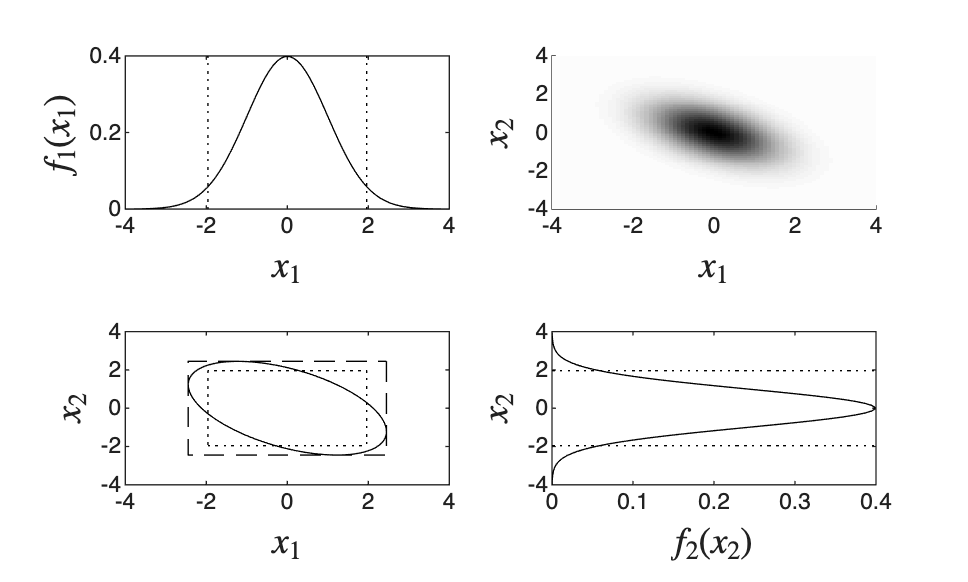

figure(1)

% plot the pdf on x1
figure(1)
subplot(2,2,1); 
p1 = normpdf(x1,mu(1),Sigma(1,1));
plot(x1,p1,'k');
hold on
line([mbox(1,1) mbox(1,1)],get(gca, 'ylim'), 'Color','black','LineStyle',':')
line([mbox(2,1) mbox(2,1)],get(gca, 'ylim'), 'Color','black','LineStyle',':')
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$f_1(x_1)$','Interpreter','latex','FontSize',14);
xlim([mu(1)-Sigma(1,1)*4 mu(2)+Sigma(1,1)*4])

% plot the pdf on x2
subplot(2,2,4); 
p2 = normpdf(x2,mu(2),Sigma(2,2));
plot(p2,x2,'k');
hold on
line(get(gca, 'xlim'), [mbox(1,2) mbox(1,2)],'Color','black','LineStyle',':')
line(get(gca, 'xlim'), [mbox(3,2) mbox(3,2)],'Color','black','LineStyle',':')
xlabel('$f_2(x_2)$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14);
ylim([mu(2)-Sigma(2,2)*4 mu(2)+Sigma(2,2)*4])

% plot the pdf on x1,x2
subplot(2,2,2)
c=linspace(0.99,0.0,64)';
C=[c,c,c];
imagesc('XData',x1,'YData',x2,'CData',F)
colormap(C);
axis([mu(1)-Sigma(1,1)*4 mu(1)+Sigma(1,1)*4 mu(2)-Sigma(2,2)*4 mu(2)+Sigma(2,2)*4])
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14); 

% plot the ellipse
subplot(2,2,3)
figure(1); 
plot(xe,ye,'k') % plot the ellipse
hold on
plot(bbox(:,1),bbox(:,2),'k--') % plot the bounding box
hold on
plot(mbox(:,1),mbox(:,2),'k:') % plot the marginal box
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14);
xlim([mu(1)-Sigma(1,1)*4 mu(1)+Sigma(1,1)*4])
ylim([mu(2)-Sigma(2,2)*4 mu(2)+Sigma(2,2)*4])

print -depsc ch3_gaussian_geom_corre.eps

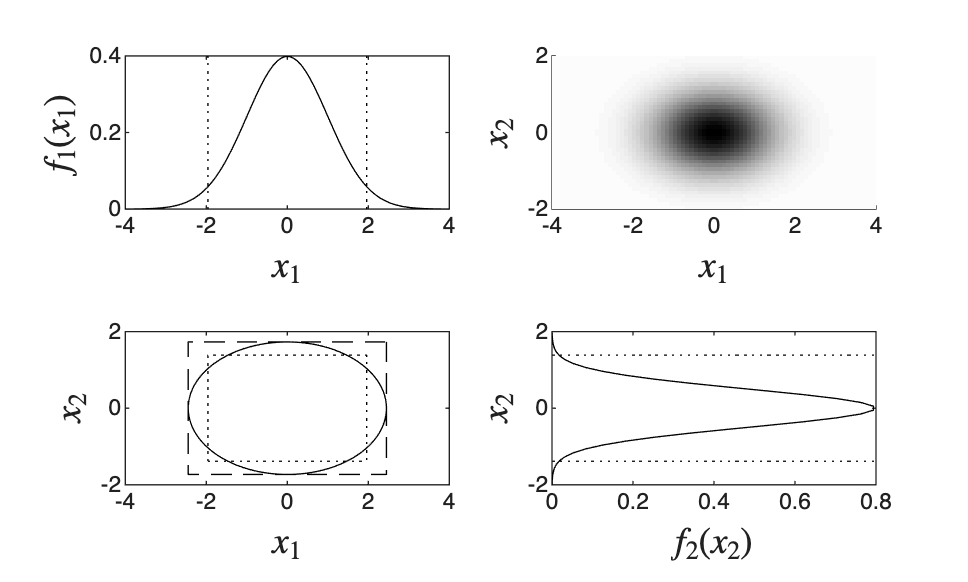


%%%%%%%%%%%%%
clc
clear all

% specify mean and covariance 
mu = [0 0];
Sigma = [1 0; 
         0 0.5]; % independent

% compute the 95% confidence interval ellipse
alpha = 0.95; % confidence 
n = 2; % dimension of variable
A = inv(Sigma); % inverse covariance
b = chi2inv(alpha, n); % confidence level on 2d from chi2 distribution
[xe, ye, major, minor, bbox] = ellipse(A, b, 100, mu); % ellipse

% 95% marginal intervals
b2 = chi2inv(alpha, 1); % confidence level on 1d from chi2 distribution
xd2 = sqrt(b2.*diag(Sigma))'; % confidence interval on 1d
mbox = repmat(mu,5,1)+ [-xd2;  [xd2(1), -xd2(2)]; xd2; [-xd2(1), xd2(2)]; -xd2];

% evaluate probability density function in domain(-3,3 and -3,3)
nmesh = 100;
x1 = linspace(-5,5,nmesh); x2 = linspace(-5,5,nmesh); 
[X1,X2] = meshgrid(x1,x2); % create mesh
F = mvnpdf([X1(:) X2(:)],mu,Sigma); % pdf on mesh
F = reshape(F,length(x2),length(x1));

% plot the pdf on x1
figure(2)
subplot(2,2,1); 
p1 = normpdf(x1,mu(1),Sigma(1,1));
plot(x1,p1,'k');
hold on
line([mbox(1,1) mbox(1,1)],get(gca, 'ylim'), 'Color','black','LineStyle',':')
line([mbox(2,1) mbox(2,1)],get(gca, 'ylim'), 'Color','black','LineStyle',':')
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$f_1(x_1)$','Interpreter','latex','FontSize',14);
xlim([mu(1)-Sigma(1,1)*4 mu(2)+Sigma(1,1)*4])

% plot the pdf on x2
figure(2)
subplot(2,2,4); 
p2 = normpdf(x2,mu(2),Sigma(2,2));
plot(p2,x2,'k');
hold on
line(get(gca, 'xlim'), [mbox(1,2) mbox(1,2)],'Color','black','LineStyle',':')
line(get(gca, 'xlim'), [mbox(3,2) mbox(3,2)],'Color','black','LineStyle',':')
xlabel('$f_2(x_2)$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14);
ylim([mu(2)-Sigma(2,2)*4 mu(2)+Sigma(2,2)*4])

% plot the pdf on x1,x2
figure(2)
subplot(2,2,2)
c=linspace(0.99,0.0,64)';
C=[c,c,c];
imagesc('XData',x1,'YData',x2,'CData',F)
colormap(C);
axis([mu(1)-Sigma(1,1)*4 mu(1)+Sigma(1,1)*4 mu(2)-Sigma(2,2)*4 mu(2)+Sigma(2,2)*4])
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14); 

% plot the ellipse
figure(2)
subplot(2,2,3)
plot(xe,ye,'k') % plot the ellipse
hold on
plot(bbox(:,1),bbox(:,2),'k--') % plot the bounding box
hold on
plot(mbox(:,1),mbox(:,2),'k:') % plot the marginal box
xlabel('$x_1$','Interpreter','latex','FontSize',14); 
ylabel('$x_2$','Interpreter','latex','FontSize',14);
xlim([mu(1)-Sigma(1,1)*4 mu(1)+Sigma(1,1)*4])
ylim([mu(2)-Sigma(2,2)*4 mu(2)+Sigma(2,2)*4])

print -depsc ch3_gaussian_geom_indep.eps

## Note

As in the book, the shape and orientation of the ellipse come from the covariance matrix (its eigenvalues and eigenvectors).